# IMPORT DATA

close all
clc
clear all

addpath("Functions\");

dir = pwd;
wind_data = readtable(strcat(dir, '\Data\Wind_data.csv')).WindSpeed_m_s_;    %already access the table

Remove NaN from data

wind_data = wind_data(~isnan(wind_data));

Turbine data

rho_air = 1.225;            % air density [kg/m3]
H = 119;                    % hub height [m]
R_rotor = 178.3/2;               % rotor radius [m]
A_rotor = pi*R_rotor^2;     % rotor area [m2]
V_rated = 11.4;               % rated wind speed [m/s]
V_ci = 4;                   % cut-in wind speed [m/s]
V_co = 25;
Jeq = 1.56e8;                % equivalent inertia [kg*m2]
b = 2e5;                  % damping (equivalent losses) coefficient [N*m*s/rad]
P_rated = 10e6;             % rated power [W]
pole_pairs = 320;           % poles pairs
magnets_flux = 19.49;       % magnets flux [Wb]
stat_resistance = 64e-3;    % stator resistance [ohm]


## Significant speeds and Kaimal Spectrums

Calculate wind significant speeds.

We will consider the following quantiles:

0.25, 0.5, 0.75

significant_speed_1 = quantile(wind_data, 0.25);  % 25 per cent of wind speeds
significant_speed_2 = quantile(wind_data, 0.5);
significant_speed_3 = quantile(wind_data, 0.75);
significant_speed_mean = mean(wind_data);

Calculate the 3 kaimal spectrums

Here we assume a turbulence intensity of 10%

The characteristic length l is 600 due to the height being above 30 meters

freq = linspace(0, 100, 1000);
S_1 = (0.1^2 * significant_speed_1 * 600) ./ ((1+ 1.5.*((freq*600)./significant_speed_1)).^(5/3));
S_2 = (0.1^2 * significant_speed_2 * 600) ./ ((1+ 1.5.*((freq*600)./significant_speed_2)).^(5/3));
S_3 = (0.1^2 * significant_speed_3 * 600) ./ ((1+ 1.5.*((freq*600)./significant_speed_3)).^(5/3));
S_mean = (0.1^2 * significant_speed_mean * 600) ./ ((1+ 1.5.*((freq*600)./significant_speed_mean)).^(5/3));


Plots

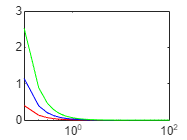

plot(freq, S_1, 'Color','r')
xscale log
xlim([0, 100])
hold on
plot(freq, S_2, 'Color','b')
plot(freq, S_3, 'Color','g')
hold off

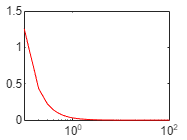



plot(freq, S_mean, 'Color','r')
xscale log

## Wind series

Now we can generate the wind time series. We will consider T = 600 seconds

T_sim = 600;
dT = 0.1;
time = 0:dT:T_sim;


%set of frequencies and phases
f_set = (1:1:length(time)) ./T_sim;
phase_1 = ((2*pi).*rand(length(time), 1))';
phase_2 = ((2*pi).*rand(length(time), 1))';
phase_3 = ((2*pi).*rand(length(time), 1))';


%wind time series
v_1 = CreateWindSeries(time, T_sim, significant_speed_1, f_set, phase_1);
v_2 = CreateWindSeries(time, T_sim, significant_speed_2, f_set, phase_2);
v_3 = CreateWindSeries(time, T_sim, significant_speed_3, f_set, phase_3);


Plot the winds

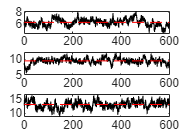

subplot(3, 1, 1)
plot(time, v_1', 'Color','black')
hold on
plot(time, repelem(significant_speed_1, length(time)), 'Color','r', 'LineStyle','--')
hold off

subplot(3,1,2)
plot(time, v_2', 'Color','black')
hold on
plot(time, repelem(significant_speed_2, length(time)), 'Color','r', 'LineStyle','--')
hold off

subplot(3,1,3)
plot(time, v_3', 'Color','black')
hold on
plot(time, repelem(significant_speed_3, length(time)), 'Color','r', 'LineStyle','--')
hold off

Noise data, needed otherwise simulink throws an error. This is used later on in the script.

We can turn on the anemometer noise with Noise_switch (1 on, 0 off)

noise_data = repelem(0, length(time));
noise_timeseries = timeseries(noise_data', time');

## Simulate

We can run the simulation with each turbine.

We willl start with the stall regulated

omega_opt = 0.776;
omega_rotor_0 = omega_opt;
Trated = P_rated/omega_opt;


% first windseries
Vw_timeseries = timeseries(v_1, time');
stall_out_1 = sim("Models\stall_regulated_WT");

% second windseries
Vw_timeseries = timeseries(v_2, time');
stall_out_2 = sim("Models\stall_regulated_WT");

% third windseries
Vw_timeseries = timeseries(v_3, time');
stall_out_3 = sim("Models\stall_regulated_WT");

Now we can do the same with the pitch regulated turbine

First we start by defining a few parameters needed for the simulation

% -- BUILD AXIS
theta_vec = (0:5:30)';                   % blades pitch angle axis [deg]
lambda_sweep = (0.1:0.1:18)';              % tip speed ratio axis []    

% -- CREATE MAP
Cp_map = zeros(length(lambda_sweep),length(theta_vec));
for i=1:1:length(theta_vec)
    theta = theta_vec(i);
    % -- EXPONENTIAL FITTING FORMULA
    Cp_map(:,i) = PowerFactor(lambda_sweep,theta);

    % -- SINUSOIDAL FITTING FORMULA
    % Cp_map(:,i) = (0.44 - 0.0167*theta) * sin(pi/2*(lambda_sweep-3)/(7.5-0.15*theta))-(lambda_sweep-3)*0.00184*theta;
    %plot(lambda_sweep,Cp_map(:,i),'-')
    leg{i} = ['\beta = ',num2str(theta),'°'];
end
% clear('one_over_beta');

% -- FIND PEAK POWER FACTOR VALUE lambda and pitch
lambda_opt = lambda_sweep(find(~(Cp_map(:,1) - max(Cp_map(:,1)))));     % lambda corresponding to the peak (pitch = 0°)


Cp_opt = max(Cp_map(:,1)); 



Trated = Cp_opt/lambda_opt*0.5*rho_air*A_rotor.*V_rated^2*R_rotor;
Prated = 0.5*rho_air*V_rated^3*A_rotor*Cp_opt;

Noise_switch = 0;

Now we can start with the simulations

% first windseries
Vw_timeseries = timeseries(v_1, time');
omega_rotor_0 = v_1(1)*lambda_opt/R_rotor;
pitch_out_1 = sim("Models\pitch_regulated_WT");

% second windseries
Vw_timeseries = timeseries(v_2, time');
omega_rotor_0 = v_2(1)*lambda_opt/R_rotor;
pitch_out_2 = sim("Models\pitch_regulated_WT");

% third windseries
Vw_timeseries = timeseries(v_3, time');
omega_rotor_0 = v_3(1)*lambda_opt/R_rotor;
pitch_out_3 = sim("Models\pitch_regulated_WT");

## Energy comparison

We can now compare the average power produced in the 3 cases

stall_avg_pw_1 = mean(stall_out_1.P_gen)

stall_avg_pw_1 = 9.2721e+05

stall_avg_pw_2 = mean(stall_out_2.P_gen)

stall_avg_pw_2 = 5.6716e+06

stall_avg_pw_3 = mean(stall_out_3.P_gen)

stall_avg_pw_3 = 9.2181e+06


pitch_avg_pw_1 = mean(pitch_out_1.P_gen)

pitch_avg_pw_1 = 1.6977e+06

pitch_avg_pw_2 = mean(pitch_out_2.P_gen)

pitch_avg_pw_2 = 5.3424e+06

pitch_avg_pw_3 = mean(pitch_out_3.P_gen)

pitch_avg_pw_3 = 8.4025e+06

As we can see, with higher wind speeds we tend to get higher power production.

Also the pitch regulated turbine tends to produce more power.

Let's now compare the energy produced

stall_tot_e_1 = (sum(stall_out_1.P_gen)) / (60*60*10)   % Energy produced in the timeframe [Wh]

stall_tot_e_1 = 1.5456e+05

stall_tot_e_2 = (sum(stall_out_2.P_gen)) / (60*60*10)

stall_tot_e_2 = 9.4543e+05

stall_tot_e_3 = (sum(stall_out_3.P_gen)) / (60*60*10)

stall_tot_e_3 = 1.5366e+06


pitch_tot_e_1 = (sum(pitch_out_1.P_gen)) / (60*60*10)

pitch_tot_e_1 = 2.8300e+05

pitch_tot_e_2 = (sum(pitch_out_2.P_gen)) / (60*60*10)

pitch_tot_e_2 = 8.9055e+05

pitch_tot_e_3 = (sum(pitch_out_3.P_gen)) / (60*60*10)

pitch_tot_e_3 = 1.4007e+06

Now compare the 2 turbines in the different scenarios:

diff_low_wind = pitch_tot_e_1 / stall_tot_e_1

diff_low_wind = 1.8310

diff_mid_wind = pitch_tot_e_2 / stall_tot_e_2

diff_mid_wind = 0.9419

diff_high_wind = pitch_tot_e_3 / stall_tot_e_3

diff_high_wind = 0.9115

We can notice how the pitch regulated turbine tends to have a higher energy production, especially at low wind speeds.

Now we can look at how the actual power production compares to the theoretical power production.

This will be done for the medium wind speed (0.5 quantile) of each turbine.

% STALL REGULATED TURBINE
% Calculate lambda and Cp

I1_stall = find(v_2<V_ci);
I2_stall = find(v_2>=V_ci & v_2<=V_co);

lambda_stall = (omega_opt*R_rotor)./v_2;
Cp_stall = PowerFactor(lambda_stall, 0);
Cp_stall(find(Cp_stall<0)) = 0;

Pw_stall_theoretical = 0*v_2;
Pw_stall_theoretical(I2_stall) = 0.5*rho_air*v_2(I2_stall).^3*A_rotor.*Cp_stall(I2_stall);

stall_efficienty_theoretical = stall_avg_pw_2 / mean(Pw_stall_theoretical)

stall_efficienty_theoretical = 0.9840




% PITCH REGULATED

I1_pitch = find(v_2<V_ci);
I2_pitch = find(v_2>=V_ci & v_2<=V_rated);
I3_pitch = find(v_2>V_rated & v_2<=V_co);
I4_pitch = find(v_2>V_co);


Pw_pitch_theoretical = 0*v_2;
Pw_pitch_theoretical(I2_pitch) = 0.5*rho_air*v_2(I2_pitch).^3*A_rotor*Cp_opt;
Pw_pitch_theoretical(I3_pitch) = Prated;


pitch_efficienty_theoretical = pitch_avg_pw_2 / mean(Pw_pitch_theoretical)

pitch_efficienty_theoretical = 0.8704

We notice how the stall turbine has a higher efficiency. This seems strange, however if we look at the theoretical power we notice that it is much lower than the pitch regulated turbine.

This means that the pitch regulated model is a bit far from the theoretical limit. One reason for this could be the limit we imposed in the pitch control of the blades, which is not fast enough compared to the changes in wind speeds.

## ANEMOMETER NOISE

We will simulate now the presence of noise on the anemometer in the pitch regulated model of the turbine.

There are mainly 2 types of wind sensors: ultrasonic (usually more precise but expensive) and mechanical (lower precision but cheaper).

We model the noise as a random signal generated by a normal distribution with mean equal to zero and standard deviation equal to 0.1 (meant as wind speed in m/s).

This noise will be added in the model in the pitch control. We will not add it to the Wind Power Calculation function due to the fact that it depends on the actual wind rather than the signal coming from a sensor.

We will consider the case with the 0.5 quantile wind speed.

Noise_switch = 1;

noise_mean = 0;
noise_sd = 0.5;

rng("default");  %for reproducibility
noise_data = normrnd(noise_mean, noise_sd, [length(time), 1]);
noise_timeseries = timeseries(noise_data, time');


Vw_timeseries = timeseries(v_2, time');
omega_rotor_0 = v_2(1)*lambda_opt/R_rotor;
pitch_out_noise = sim("Models\pitch_regulated_WT");

pitch_avg_pw_noise = mean(pitch_out_noise.P_gen)

pitch_avg_pw_noise = 5.3424e+06


noise_efficiency = pitch_avg_pw_noise / pitch_avg_pw_2

noise_efficiency = 1

We can see how the produced power is pretty much the same with a standard deviation equal to 0.5

If we low the standard deviation to 0.1 the model with noise seems to produce a little bit more power (0.1%), but this difference might simply be a lucky coincidence. It is very small anyway.

We can reconduce this similarity in power production to the fact that the wind is very variable itself, and adding noise to the sensor does not affect the power production since we are already reaching the pitch rate limits due to the high wind speed variability.